**Ercihan Kara - 2375160**

**Beste Öztop - 2375624**

## Term Project Part 2

Necessary section where fundamental of the project are built for the subsequent parts!

**Create the desired signal based on the user's choices:**

clear all

% USER INTERFACES
% initial interface to decide on whether the mic is used or a file is utilized or a
% custom signal is going to be created:

type = "none";

user_int_decide = {'Input type (mic or file or custom):'};
title_inp = 'Choose input type';
dims = [1 80];
type_input = inputdlg(user_int_decide, title_inp, dims);

if type_input == "mic"
    type = "mic";
elseif type_input == "file"
    type = "file";
else
    type = "custom";
end

if type == "mic"
    % user interface to get the sampling rate and length of the signal:

    user_int_mic = {'A-to-D sampling rate (Hz):','Length of the generated data (sec):'};
    title_inp = 'Type the sampling rate, and length of voice';
    dims = [1 80];
    defalut_input = {'8000', '5'};
    mic_inputs = inputdlg(user_int_mic, title_inp, dims, defalut_input);

elseif type == "file"
    % user interface to get the file address

    user_int_file = {'File address:'};
    title_inp = 'Type the address of the file';
    dims = [1 80];
    file_input = inputdlg(user_int_file, title_inp, dims);

else
    % user interface to get sampling rate and length for the custom signal

    user_int_custom = {'Signal frequency (Hz):','Sampling rate (Hz):','Length of the signal (sec):'};
    title_inp = 'Type the signal frequency, sampling rate, and length of custom signal';
    dims = [1 80];
    custom_inputs = inputdlg(user_int_custom, title_inp, dims);
end

% First consider the mic case:
% Create an audiorecorder object with the specified sampling rate using one channel:
if type == "mic"
    % audiorecorder creates and returns an audiorecorder object with specified properties

    samp_rate = str2double(mic_inputs(1)); % 8000 default
    bits = 8; % default
    channels = 1; % default
    ID = -1; % default

    % object created
    obj = audiorecorder(samp_rate, bits, channels, ID);

    % record the input voice
    % disp("SPEAK")
    duration = str2double(mic_inputs(2)); % users' desired time period
    recordblocking(obj, duration);
    % disp("FINITO")

    % save the voice data
    voice = getaudiodata(obj, 'double');

    % play it to check
    play(obj);

% Then consider the file case:
elseif type == "file"
    % audioread reads data from the file, returns sampled data and sample
    % rate for the data
    display(file_input)
    [voice, samp_rate] = audioread(char(file_input));
    voice = mean(voice, 2);

% And consider the custom case:
else
    % create a sinusoidal signal for the "implementation" section as the
    % custom signal
    sig_freq = str2double(custom_inputs(1));
    samp_rate = str2double(custom_inputs(2));
    duration = str2double(custom_inputs(3));
    t_custom = 0:duration-1;

    % sinusoidal signal: 𝑥(𝑡)=𝐴cos(2𝜋𝑓𝑡+𝜃) as an example
    magn = 1; % default assigned
    phase = 0; % default assigned
    voice = magn*cos(2*pi*sig_freq*t_custom + phase);
    plot(t_custom, abs(voice))
end

**Sound Signal and its time domain plot**

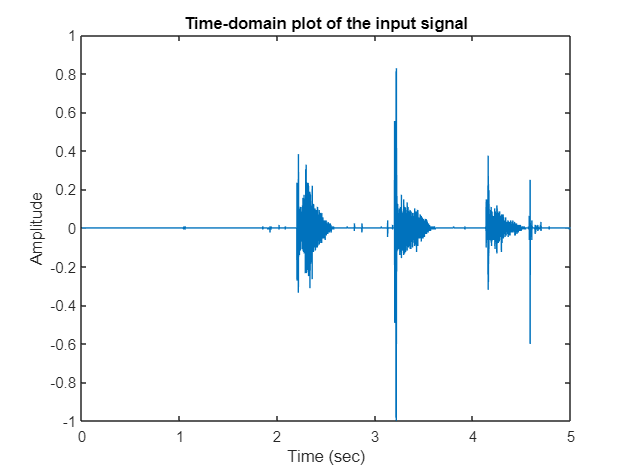

% Plot time domain representation of the sound signal

if type ~= "file"
    t_axis = linspace(0, duration-1, duration*samp_rate);
    plot(t_axis, voice);
else
    plot(voice);
end
title('Time-domain plot of the input signal');
xlabel("Time (sec)");
ylabel("Amplitude");

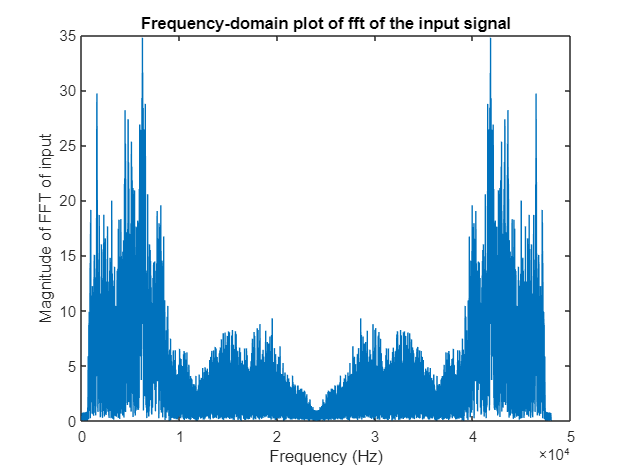


% Plot frequency domain representation of the sound signal

plot(abs(fft(voice)))
title('Frequency-domain plot of fft of the input signal');
xlabel("Frequency (Hz)");
ylabel("Magnitude of FFT of input");

**Take the window signal type to create the STFT of the sound signal**

user_int_window = {'Window type (tukey, blackman, hamming, hanning, kaiser, gaussian, triangular, rectangular):','Window signal length:'};
title_inp = 'Choose window type and length';
dims = [1 80];
default_input = {'','200'};
win_inputs = inputdlg(user_int_window, title_inp, dims, default_input);

**Sound Signal and its spectrogram for the desired window**

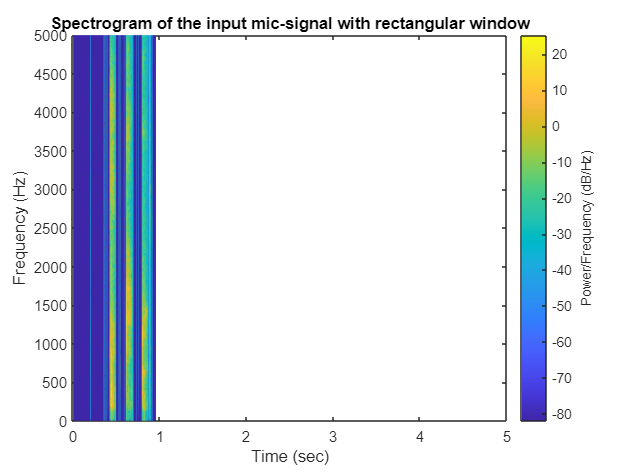

% Plot spectrogram (STFT) of the sound signal

% create STFT:
win_len = str2double(win_inputs(2));
win_type = char(win_inputs(1)); 
shift = win_len/2;
num_fft = 2*win_len;

[time, freqs, STFT] = custom_stft(voice, win_len, win_type, shift, num_fft, samp_rate);
mag_stft = abs(STFT);
freqs = freqs.';

custom_spectrogram_plot(time/(5*10^4), 10^4*freqs, mag2db(mag_stft));
if type ~= "file"
    xlim([0 (duration-1)]);
end
title("Spectrogram of the input mic-signal with " + win_type + " window");
xlabel("Time (sec)");
ylabel("Frequency (Hz)");

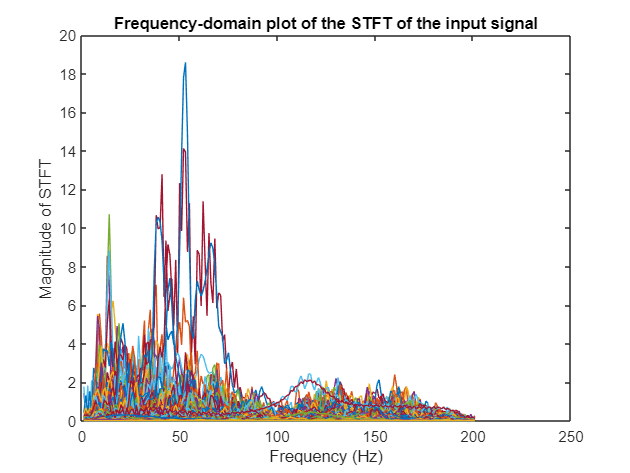

% Plot frequency domain representation of the STFT of the sound signal
plot(abs(STFT))
title('Frequency-domain plot of the STFT of the input signal');
xlabel("Frequency (Hz)");
ylabel("Magnitude of STFT");

**Divide the input signal**

holder = [];
num = 1;
j = 1;
label = 0;
count = 0;
for i=1:length(voice)
    if abs(voice(i)) > 0.001 && label == 0
        if(abs(voice(i+1)) < 0.001)
            continue;
        end
        count = 0;
        label = 1;
        holder(num, j) = voice(i);
        j = j + 1;
    elseif abs(voice(i)) > 0.001 && label == 1
        count = 0;
        holder(num, j) = voice(i);
        j = j + 1;
    elseif label == 1 && count>50
        label = 0;
        num = num + 1;
    else
        count = count + 1;
        continue
    end
end

updated_holder = [];
sizes = size(holder);
num_of_vowels = 1;
for t=1:sizes(1)
    if nnz(holder(t,:)) > length(voice)/40
        updated_holder(num_of_vowels,:) = holder(t,:);
        num_of_vowels = num_of_vowels + 1;
    end
end

**Give the instances of the vowels in the voice using plots**

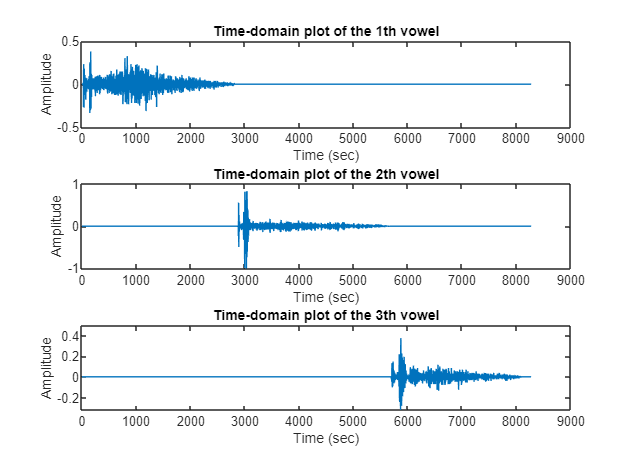

sizes_upd = size(updated_holder);

for p=1:sizes_upd(1)
    subplot(sizes_upd(1),1,p);
    plot(updated_holder(p,:));
    title("Time-domain plot of the " + p + "th vowel");
    xlabel("Time (sec)");
    ylabel("Amplitude");
end

**Find the formant frequencies of the input sound signal**

% create the formant freqs of the input signal
formant_freqs = [];
for i=1:num_of_vowels-1
    freqs_formant = formant_freq_calc(updated_holder(i,:), samp_rate);
    formant_freqs(i,1) = freqs_formant(1);
    formant_freqs(i,2) = freqs_formant(2);
    formant_freqs(i,3) = freqs_formant(3);
end

**Check whether the audio input is whispering or normal speech**

% use the STFT magnitudes to determine the whispering or normal speech
% check mag(whispering) < mag(normal_speech)

type = audio_type(STFT);
display("The audio type is " + string(type));

    "The audio type is whisper"



**Check whether the audio input is a man's or female's voice**

% use the formant frequencies to determine a man's or female's voice
gender = [];
for i=1:num_of_vowels-1
    gender(i) = detect_gender(formant_freqs(i,:), type);
    display("The gender is " + char(gender(i)));
end

    "The gender is F"

    "The gender is M"

    "The gender is F"



male = 0;
female = 0;
for i=1:num_of_vowels-1
    if gender(i) == 'M'
        male = male + 1;
    elseif gender(i) == 'F'
        female = female + 1;
    end
end
if male > female
    gen = 'M';
elseif male < female
    gen = 'F';
else
    gen = 'M';
end
gen

gen = 'F'

**Estimate the vowels on the input sound signal**

% estimate the vowels

vowels_arr = {};
for i=1:num_of_vowels-1
    vowels = vowel_estimation(formant_freqs(i,:), type, gen);
    vowels_arr(i) = vowels;
end
vowels_arr

vowels_arr = 1×3 cell array
    {'whisper_u'}    {'whisper_a'}    {'whisper_u'}
